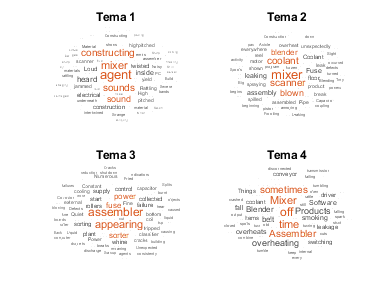

% Įkeliamas ir išskiriama tekstinių duomenų dalis
% Nurodome failo pavadinimą, iš kurio ketiname nuskaityti duomenis.
filename = "factoryReports1.csv";

% Nuskaitome duomenis iš CSV failo, kur duomenų tipas yra 'string'.
data = readtable(filename, 'TextType', 'string');

% Išskiriama teksto dalis
textData = data.Description; 
% Išskiriame teksto informaciją iš duomenų lentelės.

% Pasiruošiama tekstiniams duomenims analizuoti
documents = tokenizedDocument(textData);
% Tekstas yra tokenizuojamas ( padalinamas į žodžius).

documents = removeStopWords(documents);
% Norint pagerinti modelio tikslumą, pašaliname "stop words", kurie paprastai neturi reikšmės analizei.

documents = erasePunctuation(documents);
% Šaliname pertraukas iš teksto, kad būtų galima efektyviau jį analizuoti.

bag = bagOfWords(documents);
% Sukuriame "bag-of-words" modelį, kuris atspindi, kiek kartų kiekvienas žodis pasikartoja tekste.

% Apmokomas LDA modelis
numTopics = 7;
% Nurodome, jog norime sukurti LDA modelį su septyniomis temomis.

mdl = fitlda(bag, numTopics, 'Verbose', 0);
% Toliau apmokome LDA modelį su nurodytu skaičiumi temų.

% Vizualizuojamos temos
figure
for topicIdx = 1:4
    subplot(2, 2, topicIdx)
    wordcloud(mdl, topicIdx);
    % Vizualizuojame pirmas keturias temas naudojant "word clouds" (žodžių debesis).
    
    title("Tema " + topicIdx)
    % Pateikiame temos numerį kaip pavadinimą subplote.
end